## 9-Qubit Shor Code

Let's implement a 9-qubit Shor code, as a function that can encode an arbitrary number of qubits.

Firstly, we need to define an error that happens on one out of 9 qubits:

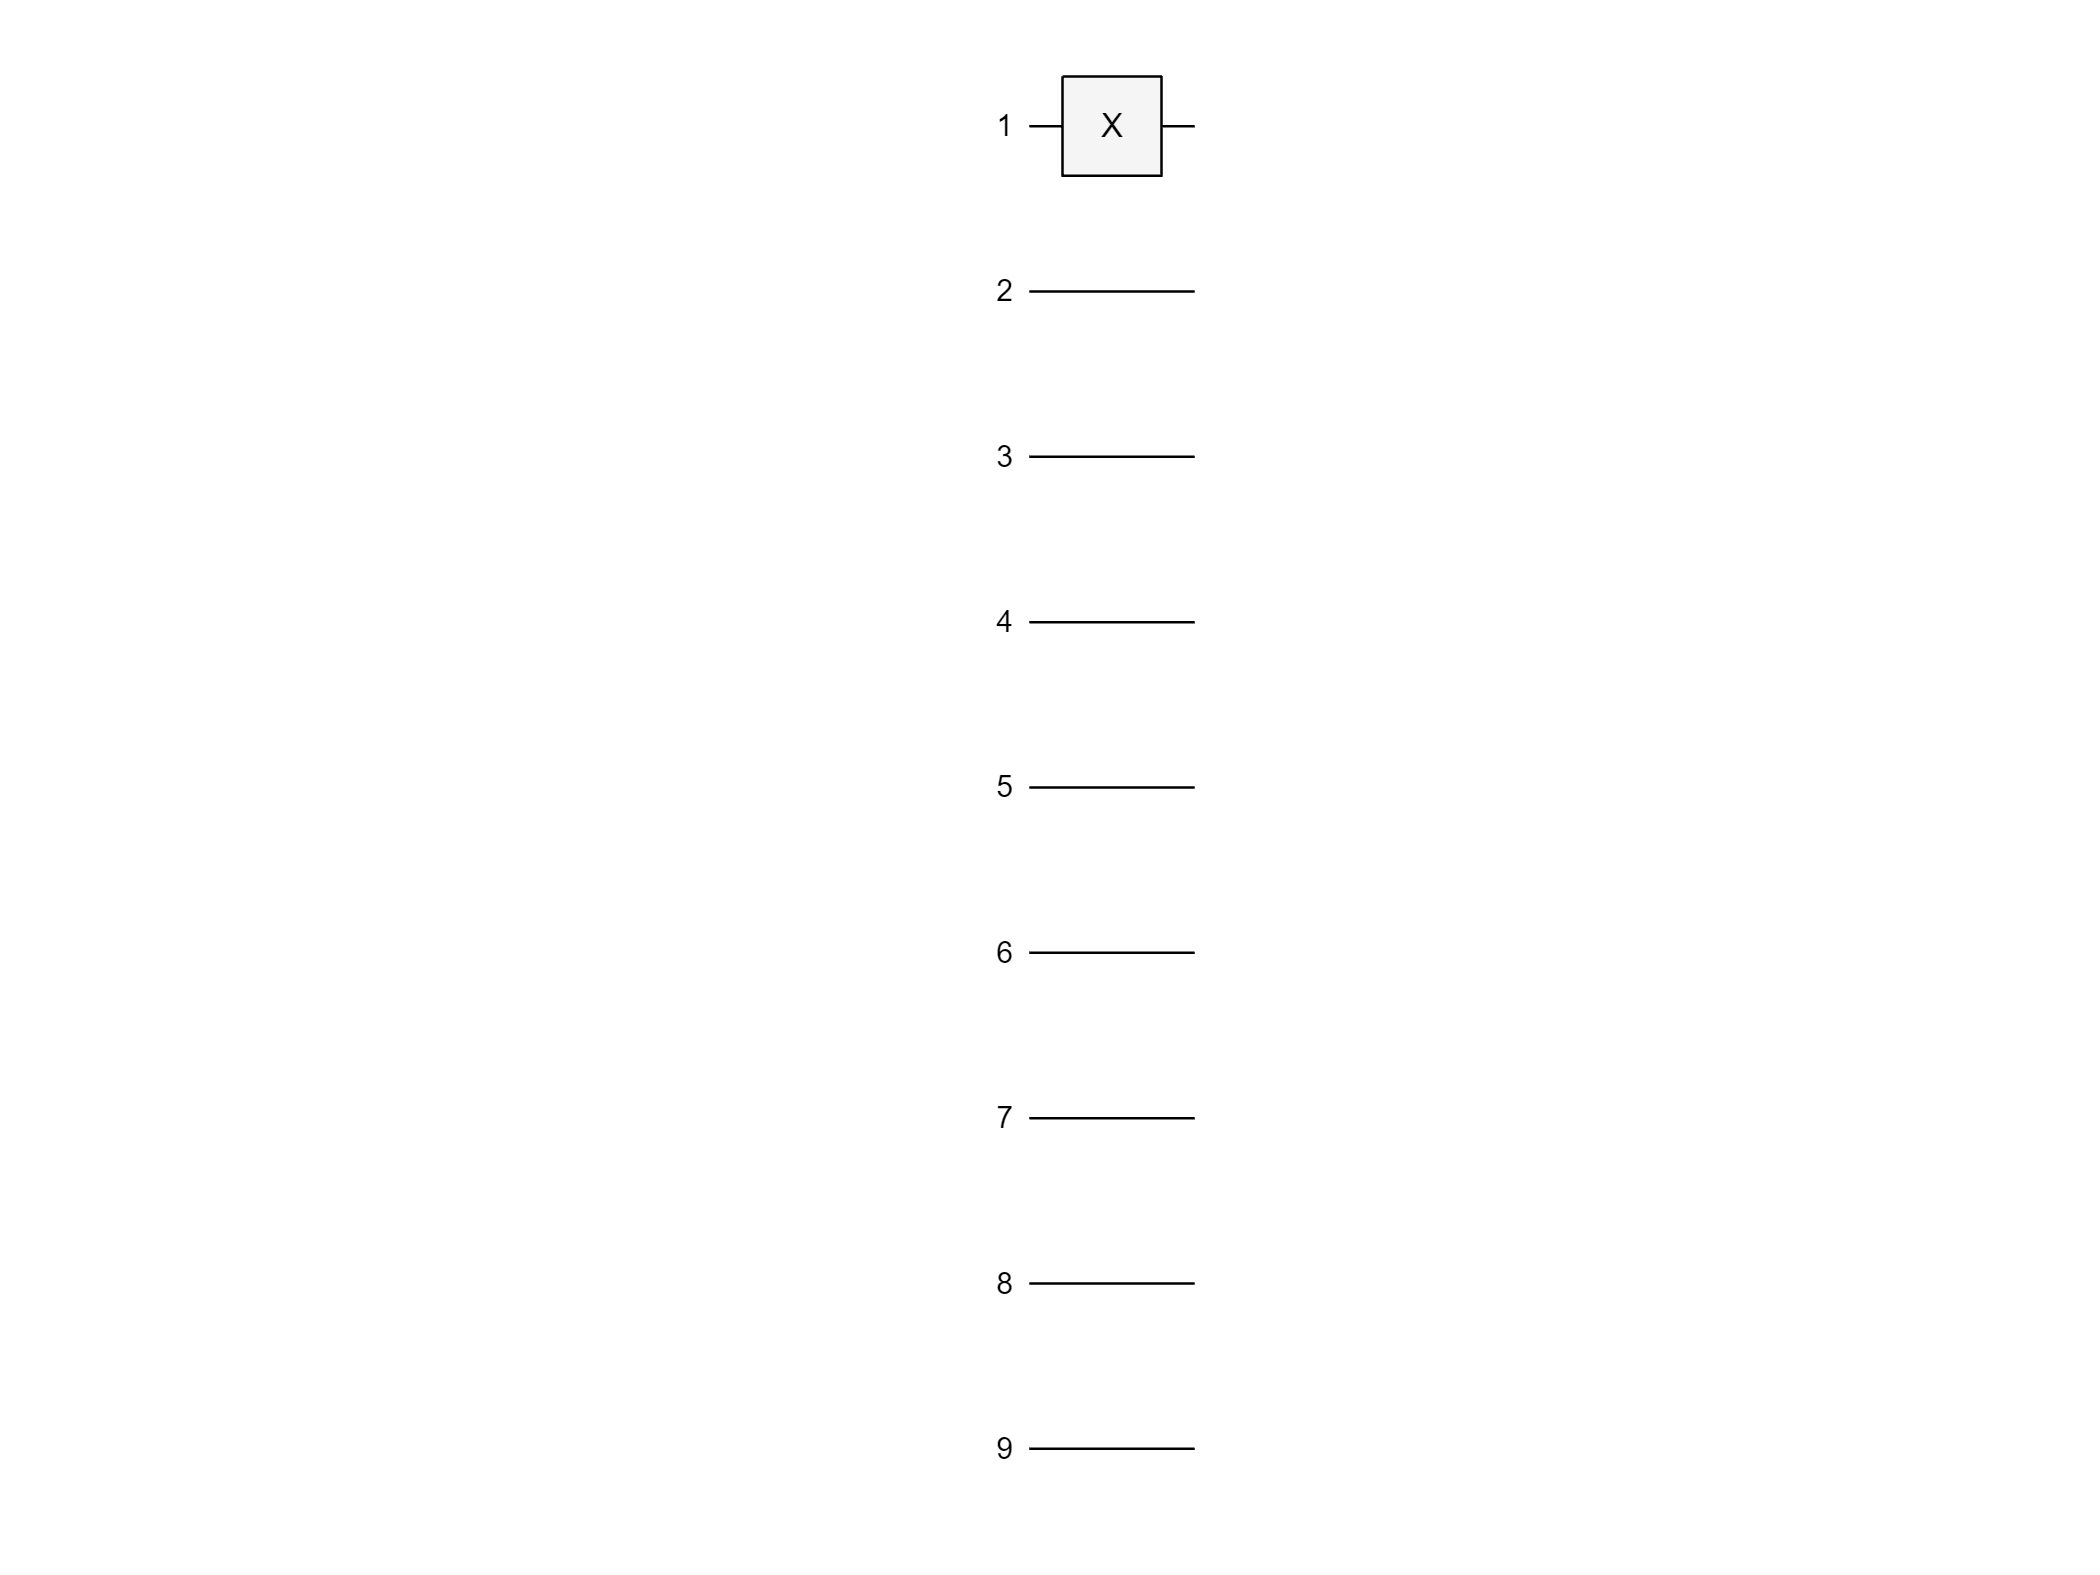

X_Error = quantumCircuit([xGate(1)], 9, Name="X");
X_Error.plot()

Now, we can define our 9-Qubit Shor Code:

function qc = shor_code_9(n, Error)
    gates = [];
    for i = 1:n
        gates = [
            gates, 
            cxGate((i-1)*9 + 1, (i-1)*9 + 1 + 3),
            cxGate((i-1)*9 + 1, (i-1)*9 + 1 + 6),
            hGate((i-1)*9 + 1),
            hGate((i-1)*9 + 1 + 3),
            hGate((i-1)*9 + 1 + 6),
            cxGate((i-1)*9 + 1, (i-1)*9 + 1 + 1),
            cxGate((i-1)*9 + 1 + 3, (i-1)*9 + 1 + 4),
            cxGate((i-1)*9 + 1 + 6, (i-1)*9 + 1 + 7),
            cxGate((i-1)*9 + 1, (i-1)*9 + 1 + 2),
            cxGate((i-1)*9 + 1 + 3, (i-1)*9 + 1 + 5),
            cxGate((i-1)*9 + 1 + 6, (i-1)*9 + 1 + 8),
            compositeGate(Error, [(i-1)*9 + 1:i*9]),
            cxGate((i-1)*9 + 1, (i-1)*9 + 1 + 1),
            cxGate((i-1)*9 + 1 + 3, (i-1)*9 + 1 + 4),
            cxGate((i-1)*9 + 1 + 6, (i-1)*9 + 1 + 7),
            cxGate((i-1)*9 + 1, (i-1)*9 + 1 + 2),
            cxGate((i-1)*9 + 1 + 3, (i-1)*9 + 1 + 5),
            cxGate((i-1)*9 + 1 + 6, (i-1)*9 + 1 + 8),
            ccxGate((i-1)*9 + 1 + 1, (i-1)*9 + 1 + 2, (i-1)*9 + 1),
            ccxGate((i-1)*9 + 1 + 4, (i-1)*9 + 1 + 5, (i-1)*9 + 1 + 3),
            ccxGate((i-1)*9 + 1 + 7, (i-1)*9 + 1 + 8, (i-1)*9 + 1 + 6),
            hGate((i-1)*9 + 1),
            hGate((i-1)*9 + 1 + 3),
            hGate((i-1)*9 + 1 + 6),
            cxGate((i-1)*9 + 1, (i-1)*9 + 1 + 3),
            cxGate((i-1)*9 + 1, (i-1)*9 + 1 + 6),
            ccxGate((i-1)*9 + 1 + 3, (i-1)*9 + 1 + 6, (i-1)*9 + 1)
            ];
    end
    qc = quantumCircuit(gates);
end

Let's test it with 1 logical qubit:

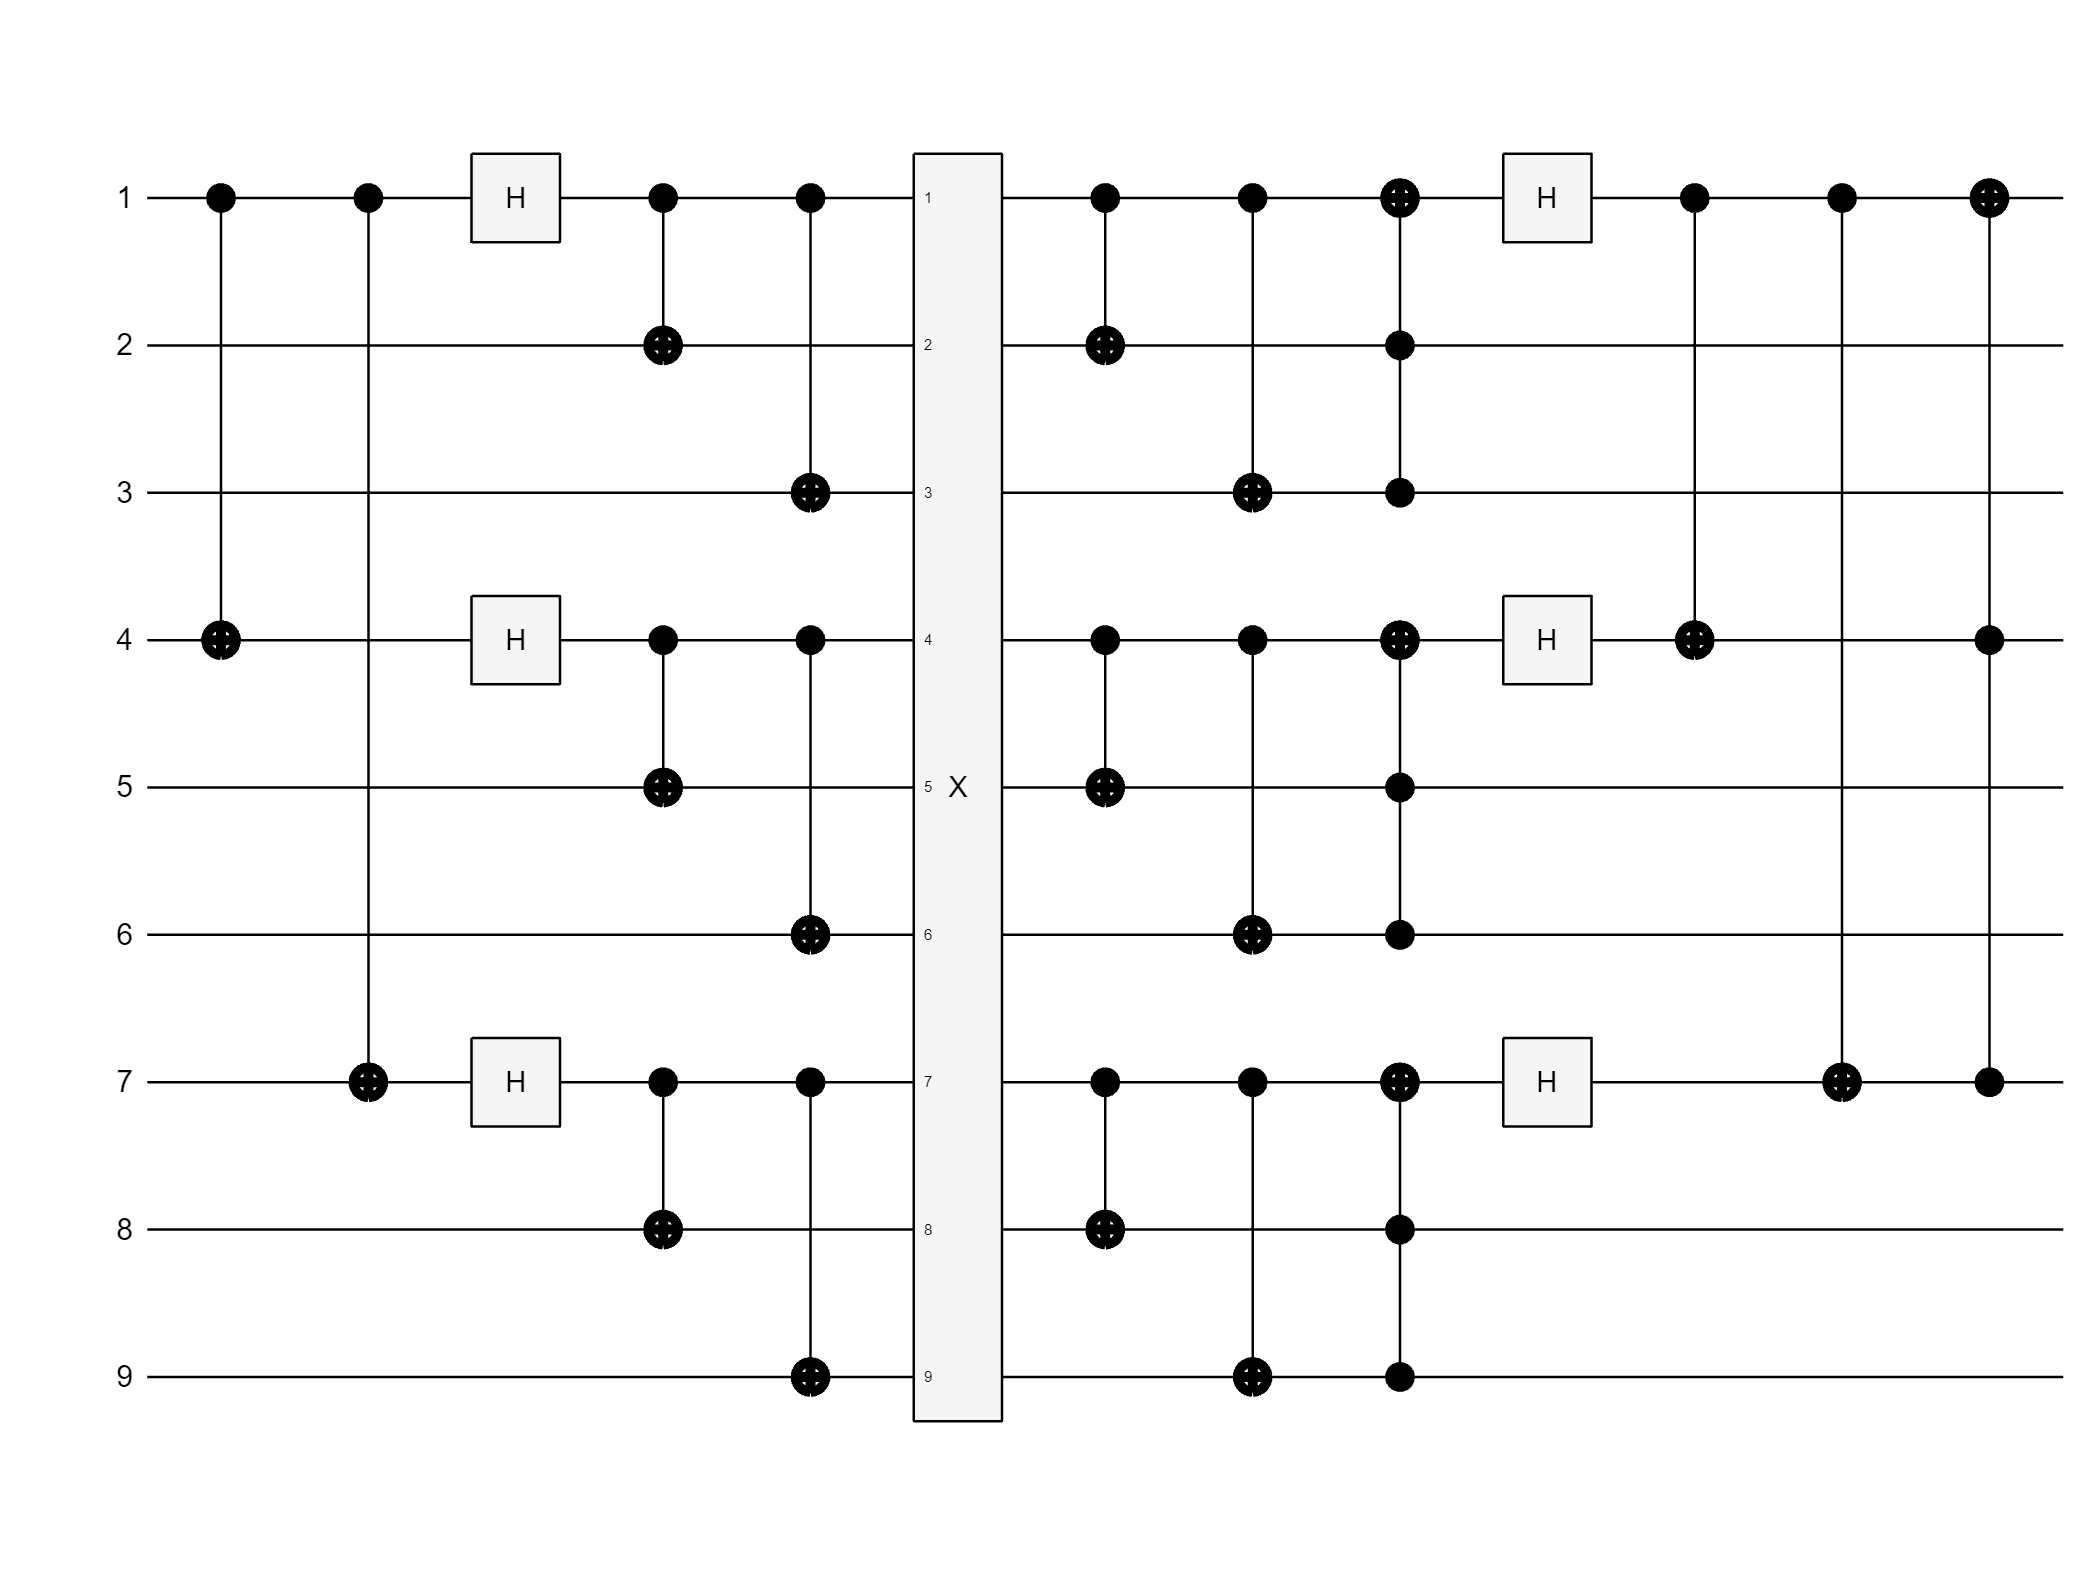

qc = shor_code_9(1, X_Error);
plot(qc)

Let's also plot it with the error gates clearly visible:

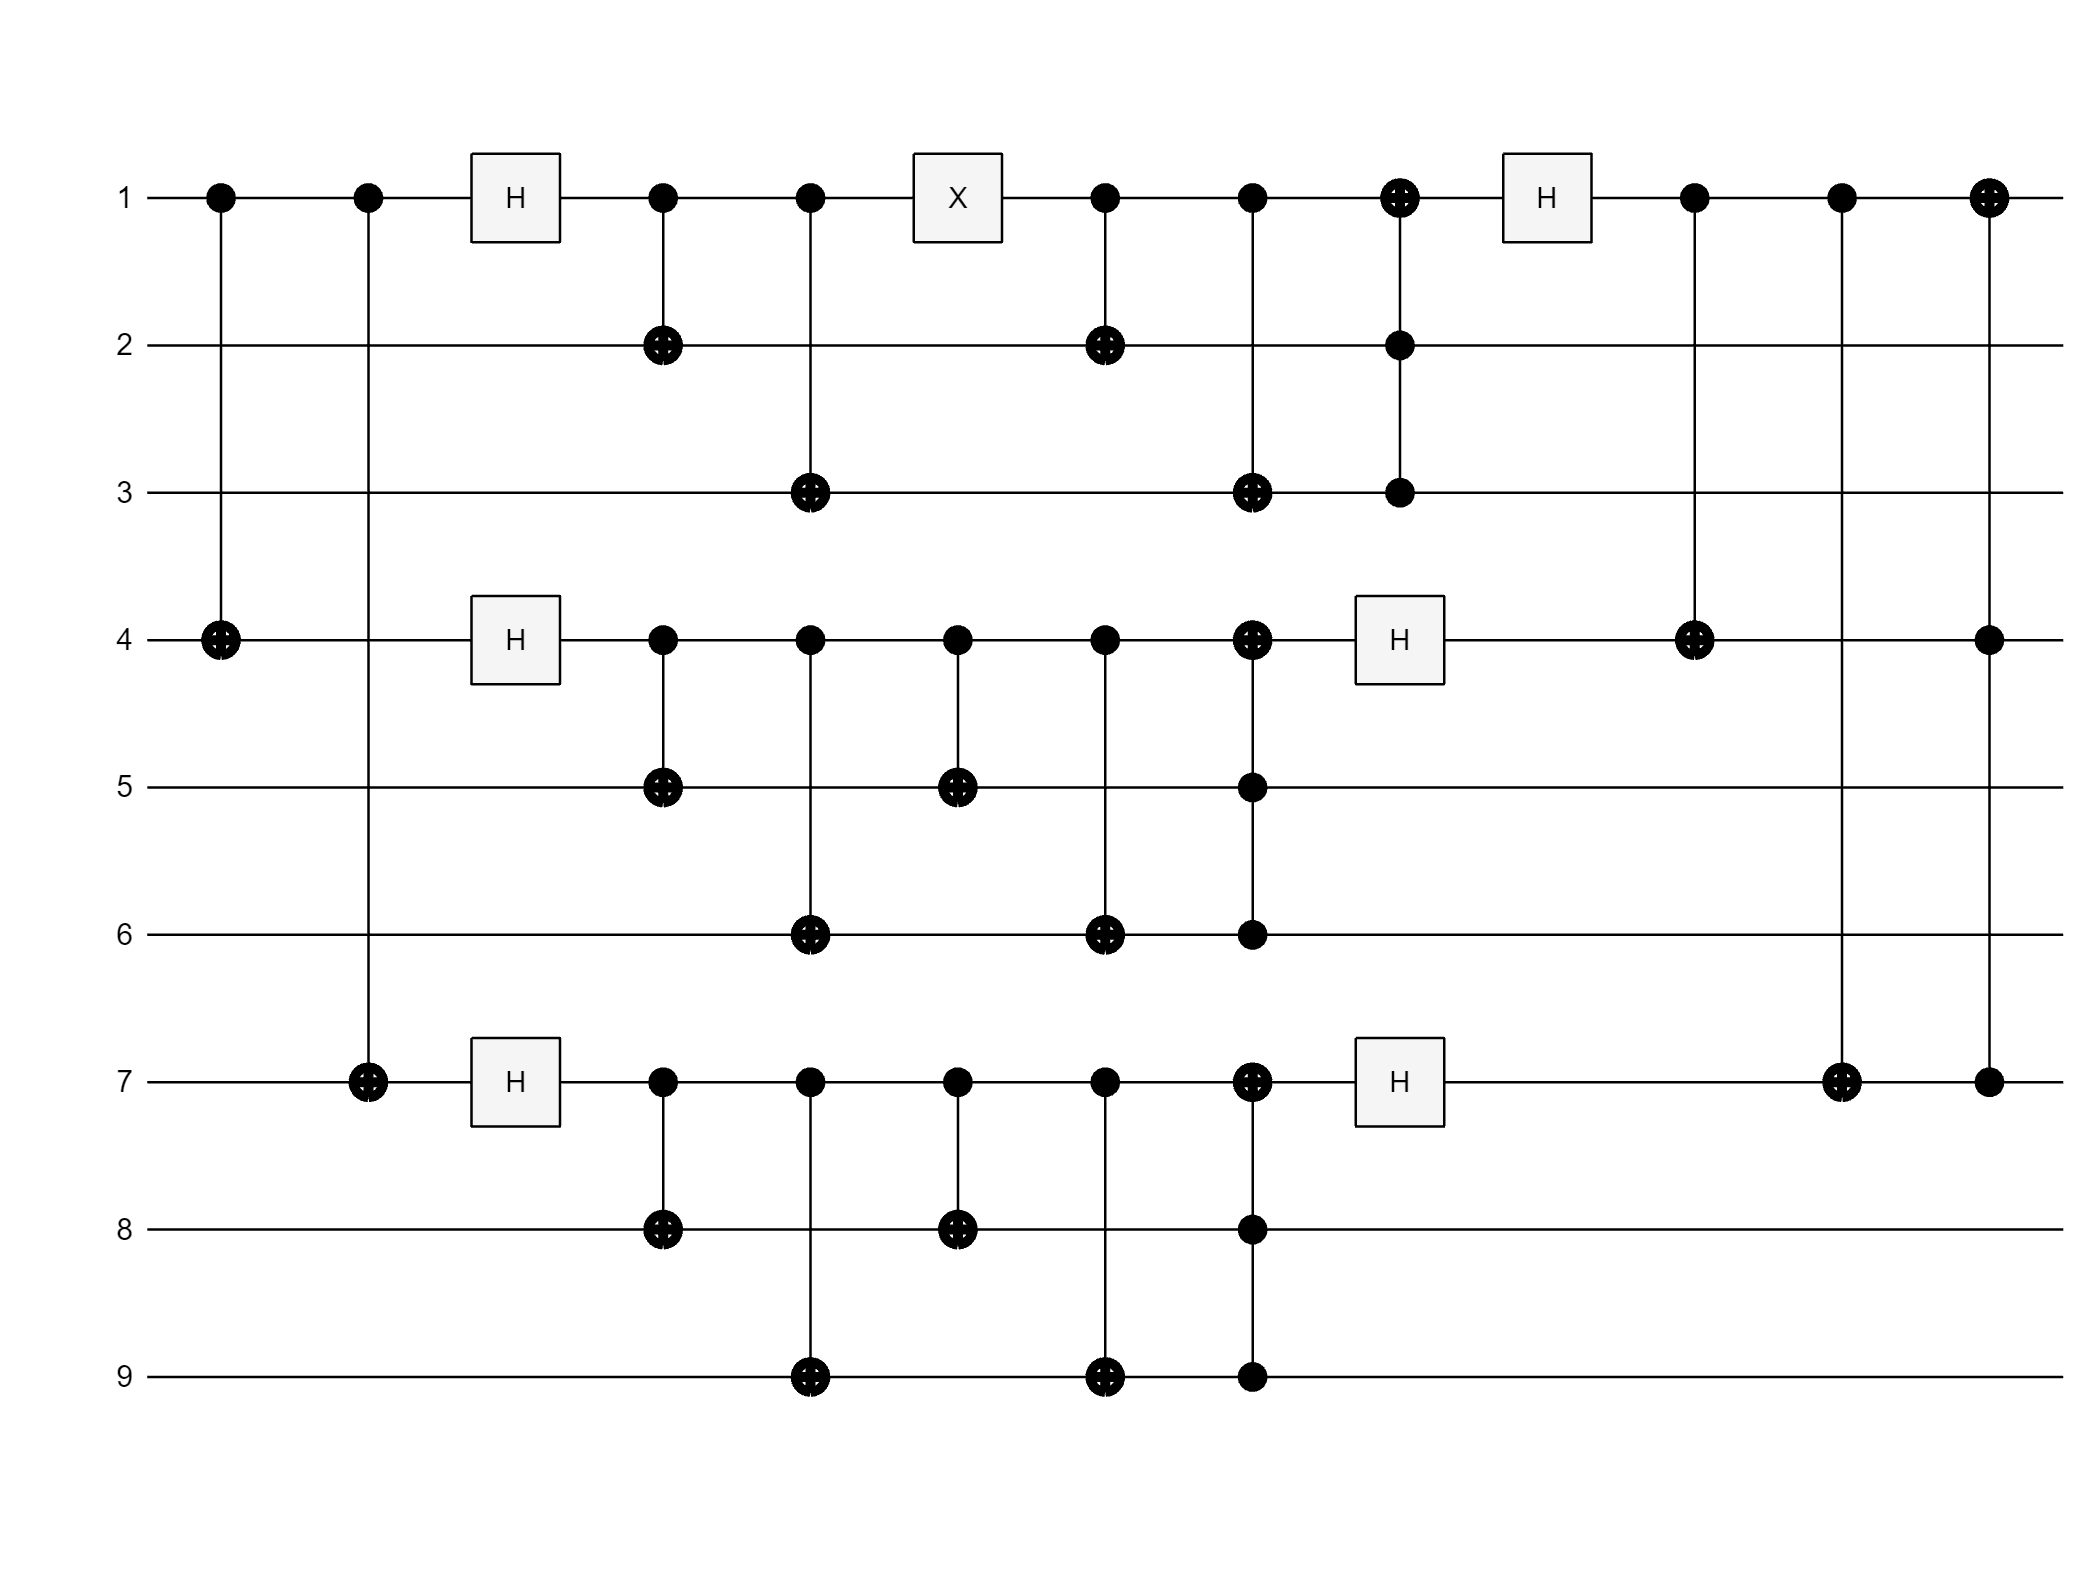

plot(unpack(qc, "recursive"))

We can see the code gates, as well as the error gates.

Let's now measure the qubits. Whatever 1-qubit error happens on qubit 1, we will read 0, since the code will have sorted it out.

%error X on qubit 1
S = simulate(qc);
[states, p] = querystates(S);
state = char(states(1));
first_qubit = state(1)

first_qubit = '0'

What about the other qubits? We can verify the other measurements:

syndrome = state(2:9)

syndrome = '11000000'

They tell us what kind of error happened.

Let's now simulate a Z error:

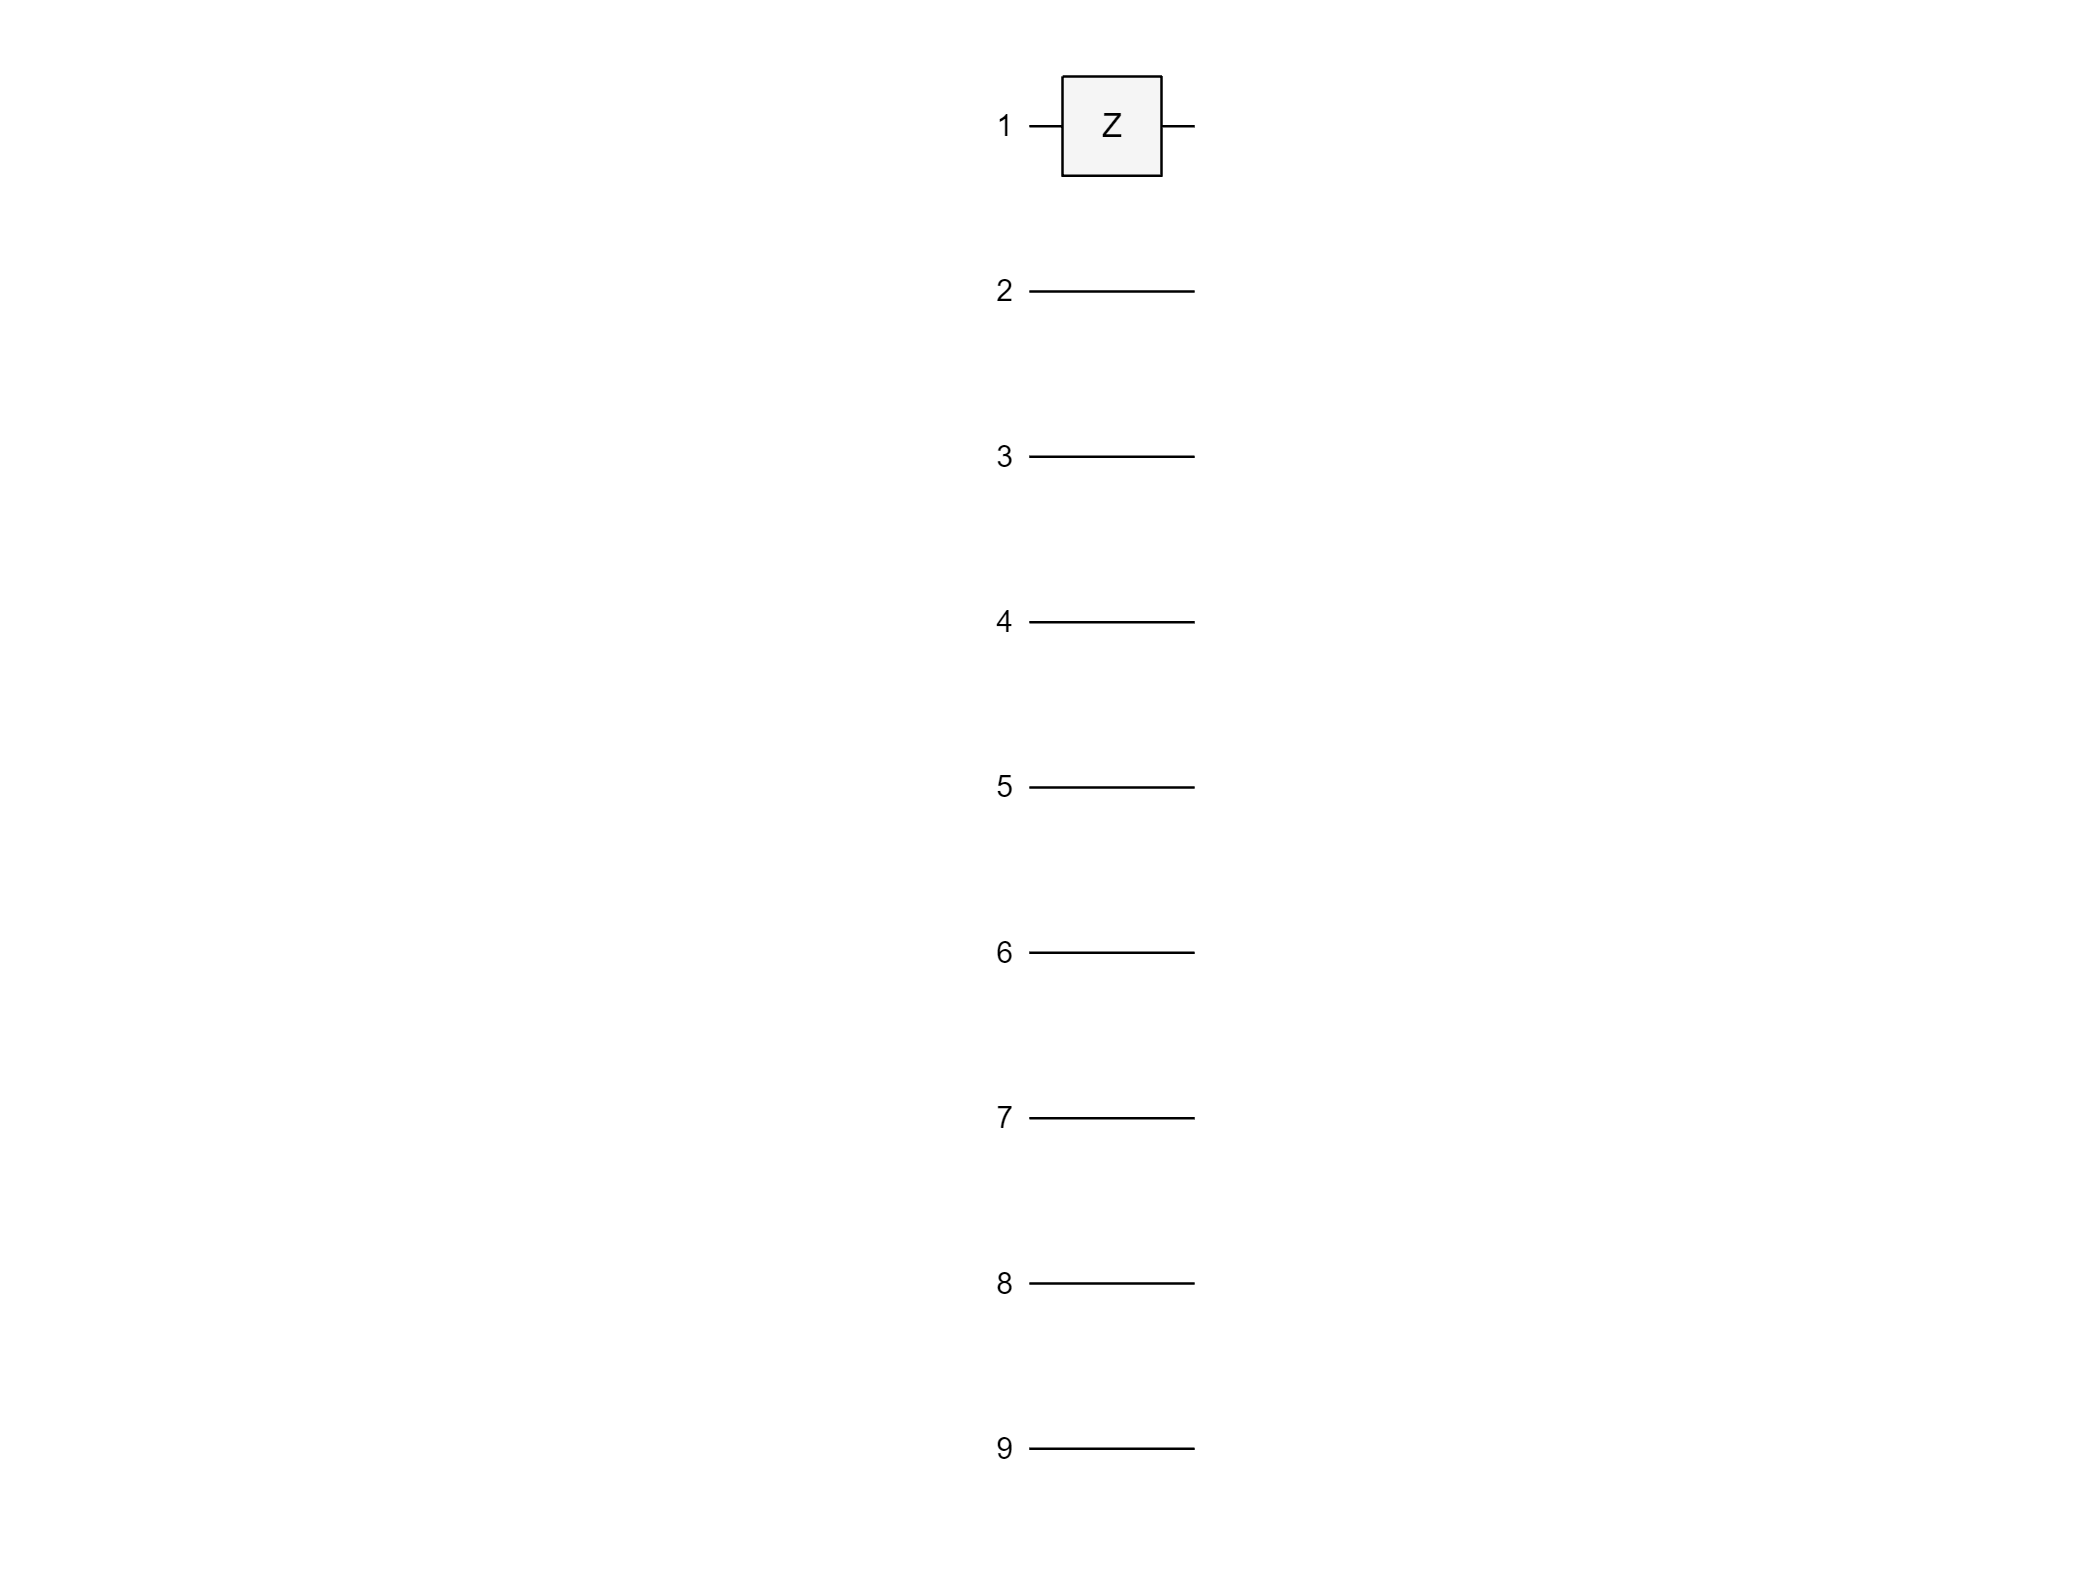

Z_Error = quantumCircuit([zGate(1)], 9, Name="Z");
Z_Error.plot()

Let's embed it in the complete code:

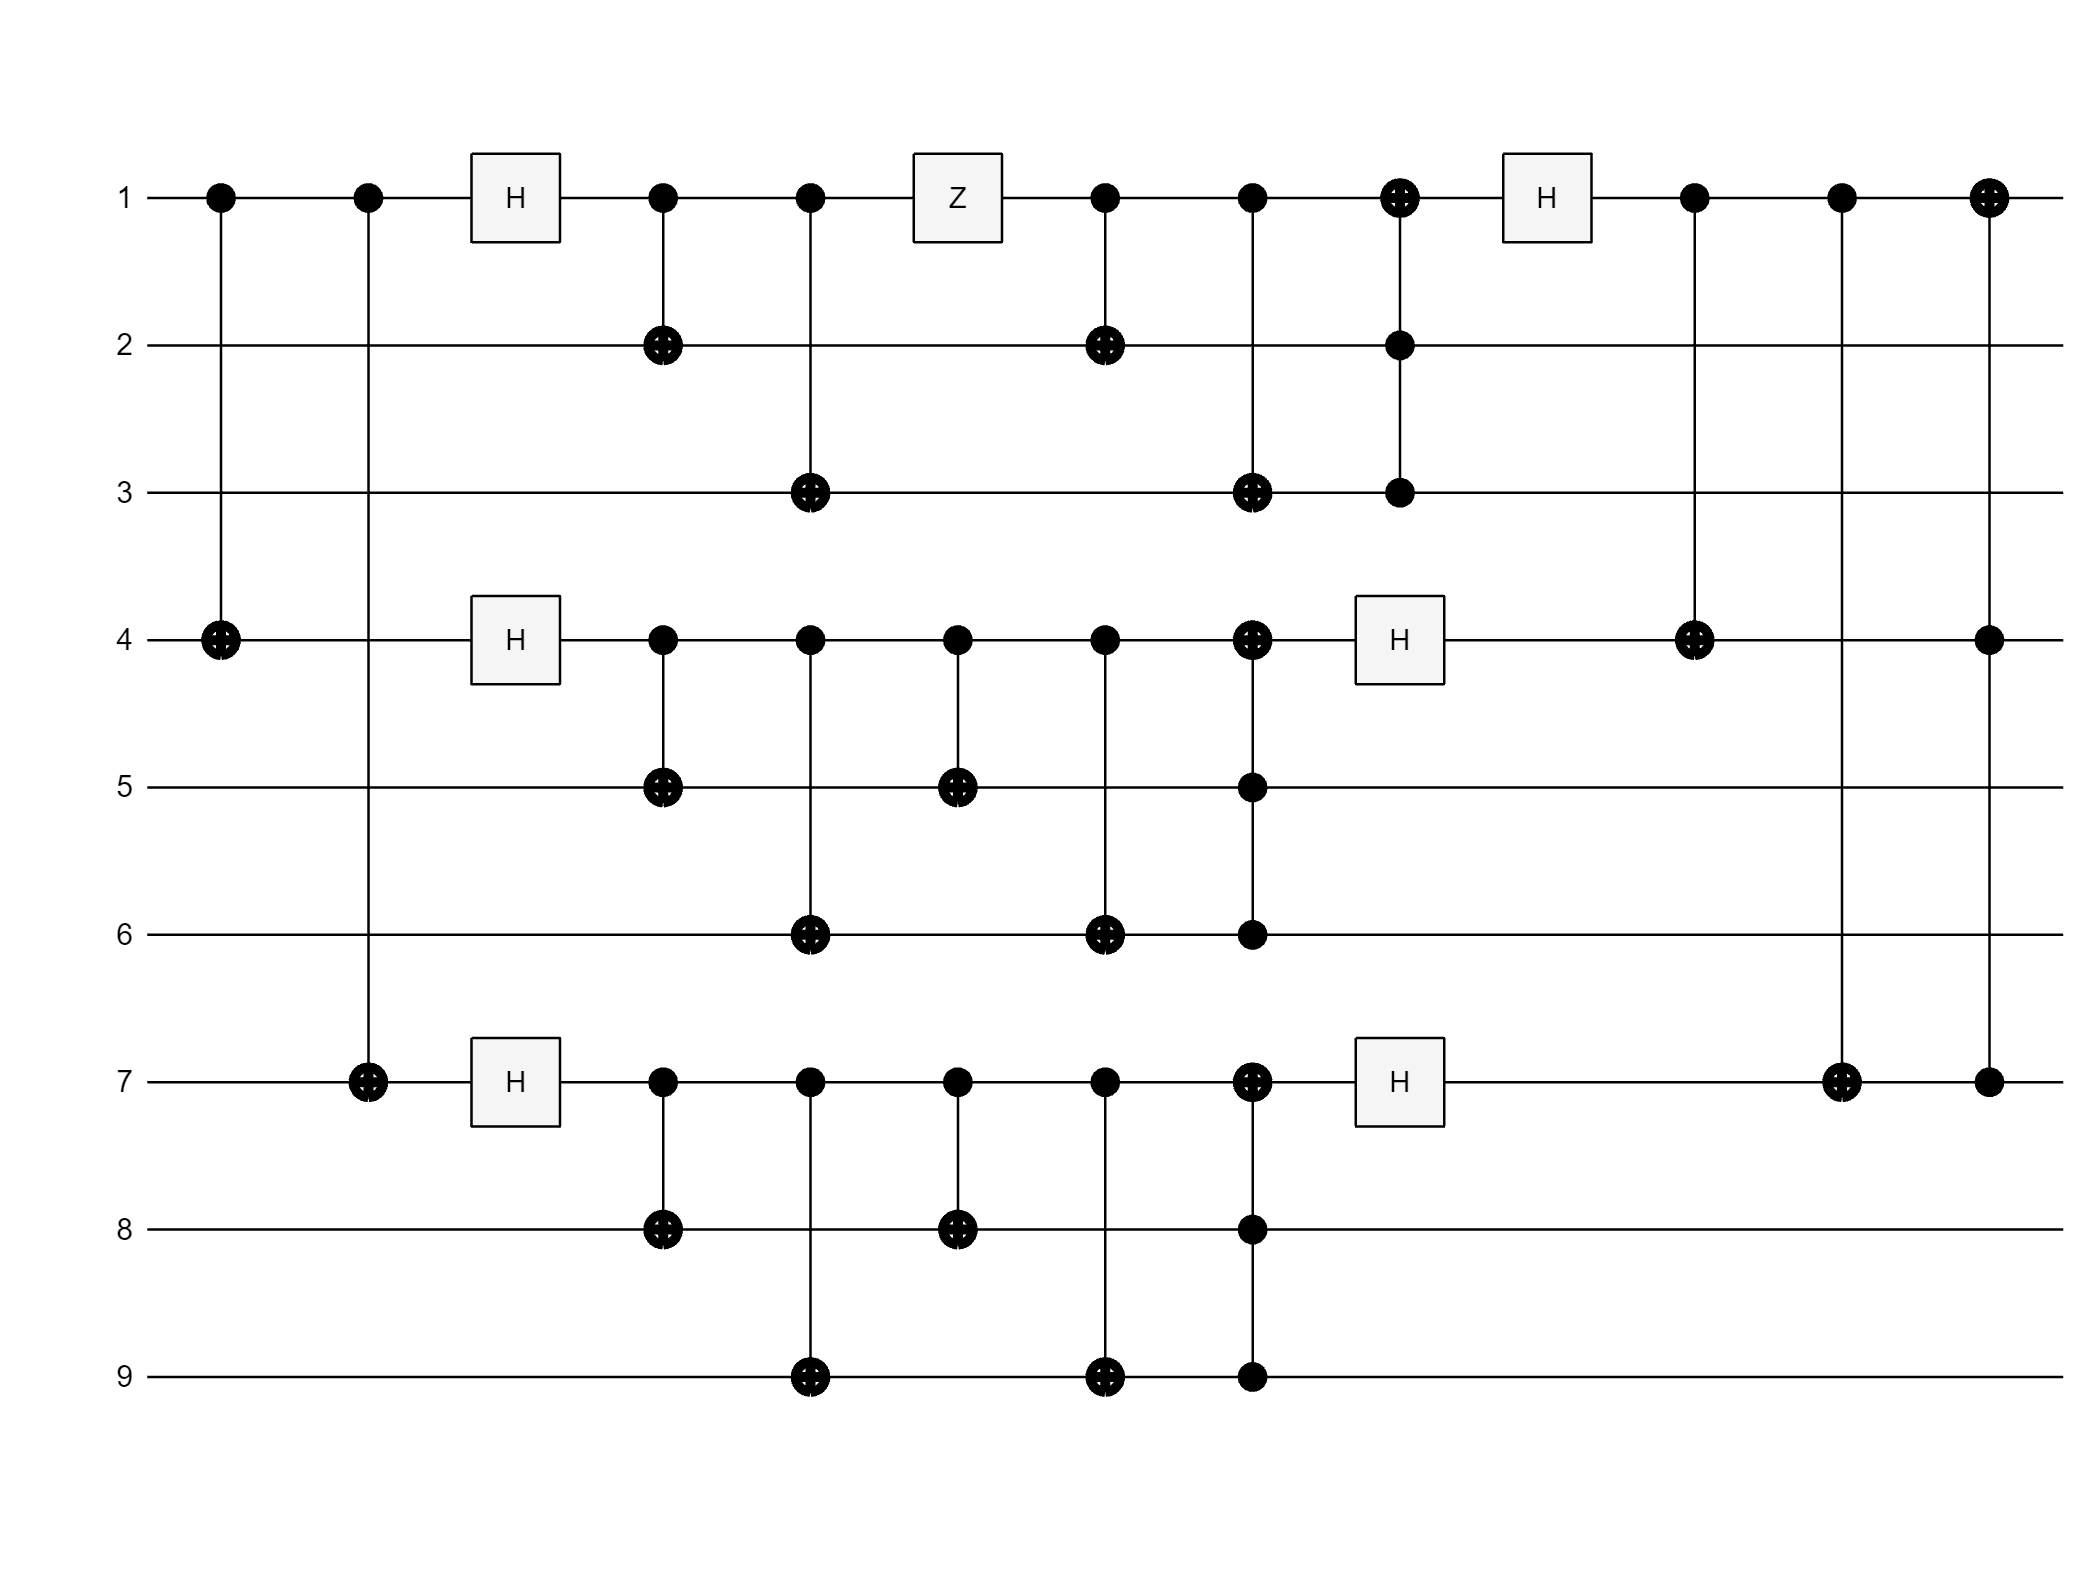

qc = shor_code_9(1, Z_Error);
plot(unpack(qc, "recursive"))

We can now simulate it and check if read 0 successfully:

%error Z on qubit 1
S = simulate(qc);
[states, p] = querystates(S);
state = char(states(1));
first_qubit = state(1)

first_qubit = '0'

We can also check the other measurements, to see if the state of the error changed:

syndrome = state(2:9)

syndrome = '00100100'

We can see the difference w.r.t. the previous X error.

We can also test multiple logical qubits:

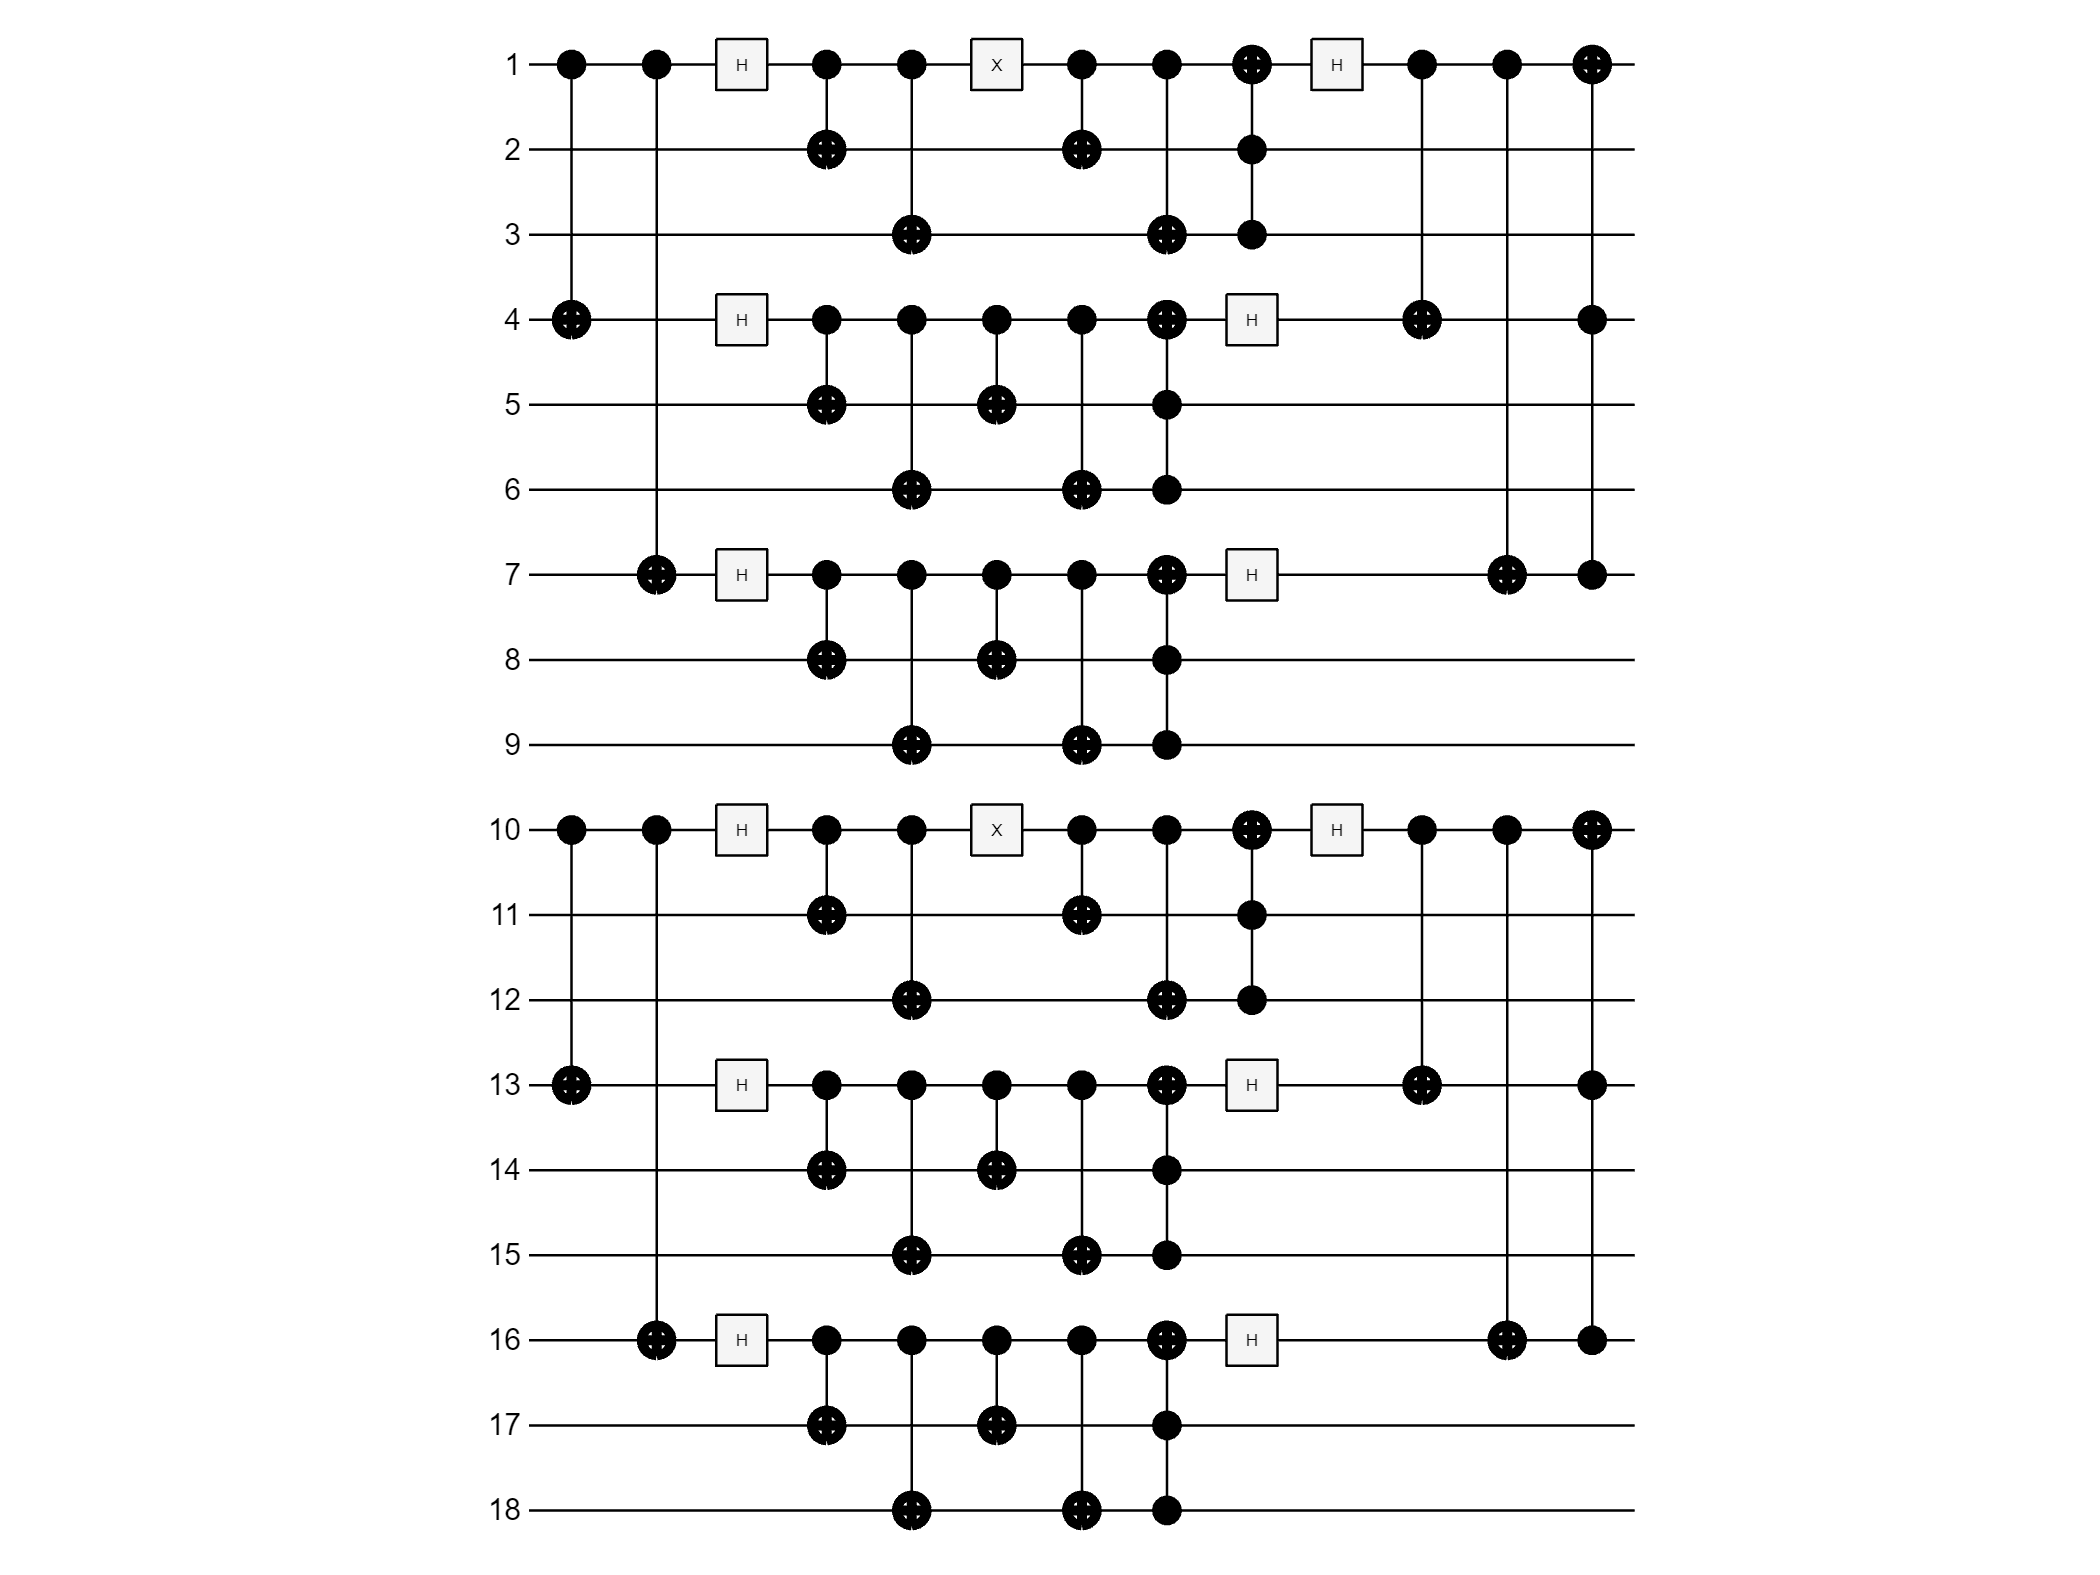

M = 3;
qc = shor_code_9(M, X_Error);
plot(unpack(qc, "recursive"))

Finally, we can verify measurements to be sure that we read 0 successfully on all logical qubits.

BEWARE!!! The more qubit you need to simulate, the more RAM you need to have. For M = 4, you need 512 GB of RAM!

S = simulate(qc);
[states, p] = querystates(S);
state = char(states(1));
for i = 1:M
    %error X on qubit (i-1)*9+1
    ith_qubit = state((i-1)*9+1);
    "qubit #" + i + ": " + ith_qubit
end

ans = "qubit #1: 0"

ans = "qubit #2: 0"